clear
targetImage = im2double(imread("imageToRep.jpg"));
targetImage = imresize(targetImage, 0.5);
load("M_XYZ2RGB.mat")
quantizeLevel = 30;
histColours = reshape(targetImage(1, 1, :),[3, 1]);
histColours(4,1) = 0;
[rMax, cMax, dMax] = size(targetImage);
for r = 1:rMax
    for c = 1:cMax
        [~, histLength] = size(histColours);
        currentColour = reshape(targetImage(r, c, :),[3, 1]);
        currentColourXYZ = inv(M_XYZ2RGB) * currentColour;
        currentColourXYZ = quantizeColour(currentColourXYZ, quantizeLevel);
        colourFound = false;
        for i = 1:histLength
            compareColour = reshape(histColours(1:3,i),[3, 1]);
            compareColourXYZ = inv(M_XYZ2RGB) * compareColour;
            compareColourXYZ = quantizeColour(compareColourXYZ, quantizeLevel);
            [meanDeltaE, Max] = calcDeltaE(currentColourXYZ', compareColourXYZ');
            
            % if same inc counter
            if meanDeltaE < quantizeLevel
                histColours(4,i) = histColours(4,i) + 1;
                colourFound = true;
                break
            end
        end
        % if we have not found the colour add it
        if colourFound == false
            histColours(1:3, end+1) = currentColour;
            histColours(4, end) = 1;
        end
    end
end

[~, histLength] = size(histColours);
histColours(4,:)

ans =         1816         311          15          83           7           4          47           4          17


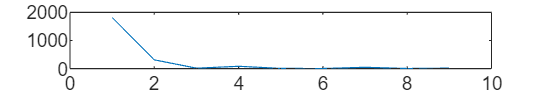

plot(histColours(4,:))

numberOfWantedColours = 10;
mostCommonColours = zeros(3, numberOfWantedColours);
for c = 1:numberOfWantedColours
    maxValue = 0;
    bestIndex = 1;
    for i = 1:histLength
        if histColours(4,i) > maxValue
            maxValue = histColours(4,i);
            bestIndex = i;
        end
    end
    histColours(4, bestIndex) = 0;
    mostCommonColours(:, c) = histColours(1:3, bestIndex);
end

mostCommonColours

mostCommonColours =     0.8206    0.9136    0.5993    0.4224    0.4588    0.2359    0.3215    0.7945    0.6909    0.8206
    0.7066    0.9094    0.6011    0.3467    0.6817    0.2352    0.3254    0.5133    0.6085    0.7066
    0.6240    0.8585    0.5692    0.1938    0.8551    0.1778    0.2645    0.5620    0.4621    0.6240


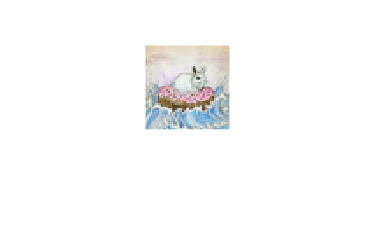

%histColours(1, :)
imshow(targetImage)

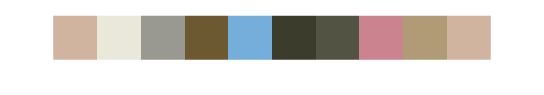

showRGB(mostCommonColours')